求解安装TMD后的响应

clc;clear;close all % 清除记录
addpath("函数/")

读入ANSYS质量刚度矩阵

% 读取梁桥模型

% 将ANSYS中的稀疏矩阵处理为完全矩阵
% Handling sparse matrices in ANSYS as full matrices 导入ANSYS MCK矩阵
% Import MCK matrix from ANSYS
hb_to_mm ('KMatrix.matrix', 'K.txt');
hb_to_mm ('MMatrix.matrix', 'M.txt');
% hb_to_mm ('CMatrix.matrix', 'C.txt');

%map the node and matrix from the KMatrix.mapping and MMatrix.mapping
Kdata = importdata('K.txt').data;
Kmatrix = zeros(Kdata(1, 1), Kdata(1, 2));

for i = 2:size(Kdata, 1)
    Kmatrix(Kdata(i, 1), Kdata(i, 2)) = Kdata(i, 3);
end

Mdata = importdata('M.txt').data;
Mmatrix = zeros(Mdata(1, 1), Mdata(1, 2));

for i = 2:size(Mdata, 1)
    Mmatrix(Mdata(i, 1), Mdata(i, 2)) = Mdata(i, 3);
end

% Cdata = importdata('C.txt').data;
% Cmatrix_DP = zeros(Cdata(1, 1), Cdata(1, 2));
%
% for i = 2:size(Cdata, 1)
%     Cmatrix_DP(Cdata(i, 1), Cdata(i, 2)) = Cdata(i, 3);
% end

% 还原对角线以上元素，使之为对称阵, ANSYS只给出下三角矩阵
% Restore the elements above the diagonal to make it a symmetric matrix, ANSYS only gives the lower triangular matrix
K = diag(diag(Kmatrix) / 2) + Kmatrix - diag(diag(Kmatrix));
K = K + K';
M = diag(diag(Mmatrix) / 2) + Mmatrix - diag(diag(Mmatrix));
M = M + M';
% C_exp = diag(diag(Cmatrix_DP) / 2) + Cmatrix_DP - diag(diag(Cmatrix_DP));
% C_exp = C_exp + C_exp';
% C =C_exp;

模态矩阵计算

% 导入质量刚度矩阵
matrix=load('matrix.mat');
K=matrix.K;
M=matrix.M;

calmodes = 5; %考虑模态数 Consider the number of modes
[eig_vec, eig_val] = eigs(K, M, calmodes, 'SM');

[nfdof, nfdof] = size(eig_vec);

for j = 1:nfdof
    mnorm = sqrt(eig_vec(:, j)' * M * eig_vec(:, j));
    eig_vec(:, j) = eig_vec(:, j) / mnorm; %振型质量归一化 Mode shape mass normalization
end

for j = 1:nfdof
    m_modal(j) = sqrt(eig_vec(:, j)' * M * eig_vec(:, j));
end

[omeg, w_order] = sort(sqrt(diag(eig_val)));
mode_vec = eig_vec(:, w_order);
Freq = omeg / (2 * pi);


for k1 = 1:calmodes
    MM_eq(k1,k1)=P_eq(k1, mode_vec, M); %P=parameters
end

for k1 = 1:calmodes
    KK_eq(k1,k1)=P_eq(k1, mode_vec, K); %P=parameters
end


设置TMD参数

mass_six_span=10007779.7;
mu=1/100;
mTMD=mass_six_span*mu;
nTMD=1;
Ftmds = 0.8:0.01:1.2;
zetaTMDs=0.05:0.002:0.1;
omegatmds = 2 * pi * Ftmds;
% cTMD = [2 * mTMD(1) * omegatmds * 0.05];
% disp(cTMD)
% 计算桥面节点的振型向量
KMmapping = importmappingmatrix('KMatrix.mapping');
UYNode=sort(KMmapping.Node(KMmapping.DOF == 'UY'));

nodeondeck = importdata('nodeondeck.txt');
nodegap = importdata('nodegap.txt');
nodeondecknew=[];
intalledlocation=[];
for k1=1:length(nodeondeck)
    if mod(k1,5)==0
        nodeondecknew=[nodeondecknew nodeondeck(k1)];
        intalledlocation=[intalledlocation nodegap(k1)];
    end
end


mode_number=1;
ifcalmode=3;

[Ftmds_M,zetaTMDs_M,nodeondeck_M]=ndgrid(Ftmds,zetaTMDs,nodeondecknew);

variables = [Ftmds_M(:),zetaTMDs_M(:),nodeondeck_M(:)];
numIterations=size(variables,1);
ppm = ParforProgressbar(numIterations,'parpool',{'local',16});
pauseTime=60/numIterations

pauseTime = 6.9488e-04

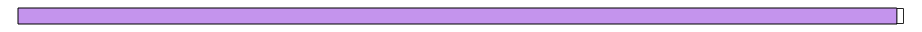

tic
parfor k1 = 1:numIterations
% parfor k1 = 1:160

    zetaTMD=variables(k1,2);
    omegaTMD=variables(k1,1)*2*pi;
    nodeTMD=variables(k1,3);

    dis1(k1)=CalData_Polynomial_withTMD_multidegree(nTMD,mTMD,zetaTMD,omegaTMD,nodeTMD,mode_number,ifcalmode,MM_eq,KK_eq,calmodes,eig_val,eig_vec);

          % do some parallel computation
      pause(pauseTime);
      % increment counter to track progress
      ppm.increment();
end

toc

历时 16768.278625 秒。


delete(ppm)
results=[variables,dis1'];
save result


## 下一节

[~,location]=min(results(:,4))

location = 35513

results(location,1)

ans = 0.8600

results(location,2)

ans = 0.0660

results(location,3)

ans = 1170

results(location,4)

ans = 0.0013

所需函数

function result = P_eq(mode, temp_vec, Matrix)
    vec = temp_vec(:, mode);
    result = vec' * Matrix * vec;
end